close all;
clc;

filename = 'dft.wav';
[y, Fs] = audioread(filename);
Fs

Fs = 22050

len_record = length(y)/Fs

len_record = 4.9902

sound(y,Fs)

word_Sample = load('wordSample.mat');
word_Sample =word_Sample.yy;
% N: the length of the data
N = length(word_Sample);
t = 0:1/Fs:N/Fs-1/Fs;
w = (0:1:N-1)*2*pi/N;
% m: the length of a segment 
m = Fs*22.5/1000;
m = round(m);
% the number of the segments
seg_num = ceil(N/m)

seg_num = 25

% matrix X stores the segments
X = zeros(seg_num,m);
for i = 1:seg_num-1
    X(i,:) = word_Sample((i-1)*m+1:i*m);
end
X(seg_num,1:N-((seg_num-1)*m)) =  word_Sample((seg_num-1)*m+1:end);
% power rxx(0)
Rxx = sum(X.^2,2);


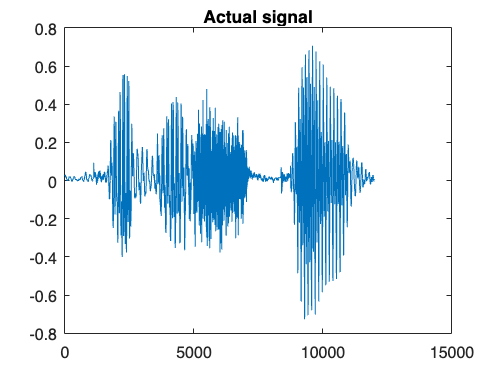

% X_est stores the estimated signal
X_est_12 = zeros(seg_num,m);
X_est_20 = zeros(seg_num,m);
% for each segment, do LPC
%for i = 1: seg_num
%   X_est = 1;
%end
p1 =12;
for i = 1:seg_num
    X_est_12(i,:) = LPC_Predict(X(i,:),p1);
end
word_Sample_est = reshape(X_est_12.',1,[]);
word_Sample_est = word_Sample_est(1:N);
error = word_Sample - word_Sample_est';
plot(1:N,word_Sample)
title('Actual signal')

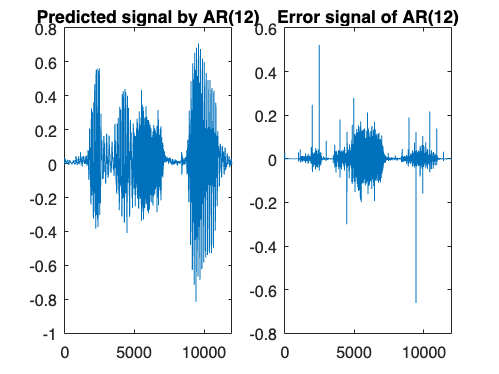

figure;subplot(1,2,1);
plot(1:N,word_Sample_est)
title('Predicted signal by AR(12)')
subplot(1,2,2);
plot(1:N,error)
title('Error signal of AR(12)')

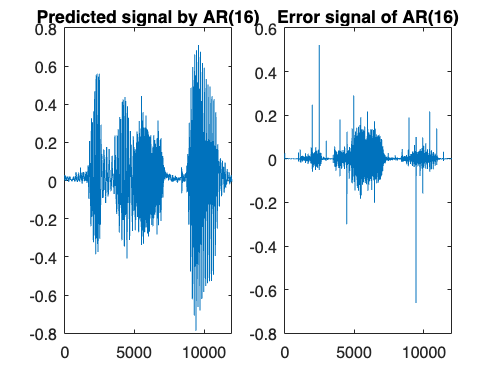


p2 =16;
for i = 1:seg_num
    X_est_16(i,:) = LPC_Predict(X(i,:),p2);
end
word_Sample_est_16 = reshape(X_est_16.',1,[]);
word_Sample_est_16 = word_Sample_est_16(1:N);
error_16 = word_Sample - transpose(word_Sample_est_16);
figure;subplot(1,2,1);
plot(1:N,word_Sample_est_16)
title('Predicted signal by AR(16)')
subplot(1,2,2);
plot(1:N,error_16)
title('Error signal of AR(16)')

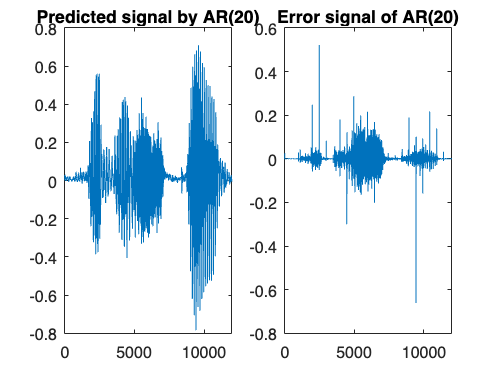

p3 =20;
for i = 1:seg_num
    X_est_20(i,:) = LPC_Predict(X(i,:),p3);
end
word_Sample_est_20 = reshape(X_est_20.',1,[]);
word_Sample_est_20 = word_Sample_est_20(1:N);
error_20 = word_Sample - transpose(word_Sample_est_20);
figure;subplot(1,2,1);
plot(1:N,word_Sample_est_20)
title('Predicted signal by AR(20)')
subplot(1,2,2);
plot(1:N,error_20)
title('Error signal of AR(20)')


MSE_12 = sum(error.^2)/N

MSE_12 = 7.1177e-04

MSE_16 = sum(error_16.^2)/N

MSE_16 = 6.6694e-04

MSE_20 = sum(error_20.^2)/N

MSE_20 = 6.3937e-04

sound(word_Sample_est_20,Fs)
%sound(word_Sample_est,Fs)

function seg_est = AR_predict(sys,seg,seg_order,p,m)

% predict seg
seg_est = zeros(size(seg));
seg_est(1:p) = seg(1:p);
for i = p+1:m
    arr = seg_est(seg_order,i-p:i-1);
    arr = arr(:);
    seg_est(i) = forecast(sys,arr,1);
end
end

function seg_est = LPC_Predict(seg,power)
[a,g]= lpc(seg,power);
seg_est = filter([0 -a(2:end)],1, seg);    
end

function seg_est = LPC_predict(a,seg,p,m)
new_a  = -a(2:end);
% predict seg
seg_est = zeros(size(seg));
seg_est(1:p) = seg(1:p);
for i = p+1:m
    new_signal = 0;
    for j = 1:p
        new_signal = new_signal+new_a(j)*seg_est(i-j);
    end
    seg_est(i) = new_signal;
end
end
